clear all
cd(fileparts(matlab.desktop.editor.getActiveFilename));

% Legge la tabella con 3 righe di intestazione
tbl = readtable("dati/acquisizione05.txt", NumHeaderLines=3);
tbl.Properties.VariableNames = ["freq", "gain", "sgain"];


mask = tbl.freq < 5e10;
freq = tbl.freq(mask);
gain   = tbl.gain(mask);
sgain  = tbl.sgain(mask);

C1=100e-9;
sC1=4e-9;
C2=47e-9;
sC2=2e-9;
R1=99.9e3;
sR1=0.1e3;
R2=6.8e3;
sR2=6.8e3*0.05;

% Funzione di trasferimento: filtro passa-banda come prodotto di due poli
H = @(p,f) abs(1./(1 + 1j*p(1)./f) .* 1./(1 + 1j*f./p(2))* 1./(1 + 1j*f./p(3)));

% Parametri iniziali: controlla le unità, qui assumo Hz
p0 = [1/(104e-9*1e6), 10000,10000];  % controlla le unità e scala se serve

covabs=1./(sgain).^2;
[popt,   R,   J,   ccovm,   MSE]   = nlinfit(freq, gain,   H, p0, "Weights", covabs);

popt

popt = 1.0e+03 *

    0.0160    3.6227    7.9563


sqrt(diag(ccovm))

ans =     0.1931
  198.5318
  993.5463


f1=1/(2*pi*R1*C1)

f1 = 15.9314

sf1=f1*sqrt((sR1/R1)^2+(sC1/C1)^2)

sf1 = 0.6375

f2=1/(2*pi*R2*C2)

f2 = 497.9817

sf2=f2*sqrt((sR2/R2)^2+(sC2/C2)^2)

sf2 = 32.6957

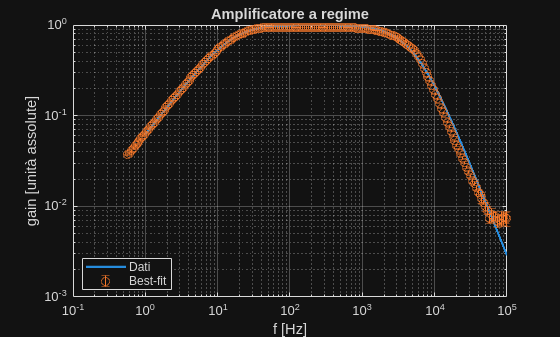




ff = logspace(0, 5, 10000);
yy = H(popt, ff);
% --- Subplot 1: modulo ---

loglog(ff, yy, 'LineWidth', 1.8)
hold on
errorbar(freq,gain, sgain, 'o')
hold  off

xlabel('f [Hz]')
ylabel('gain [unità assolute]')
legend("Dati", "Best-fit", 'Location', 'best')
title('Amplificatore a regime')
grid on

exportgraphics(gcf, "grafici/PBFdisaccoppiato+LPF_Opamp.pdf", 'ContentType', 'vector');

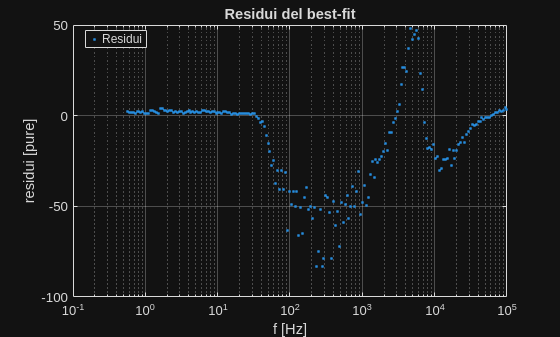


semilogx(freq,R,'.')
xlabel('f [Hz]')
ylabel('residui [pure]')
legend("Residui", 'Location', 'best')
title('Residui del best-fit')
grid on

% --- Esporta la figura ---
exportgraphics(gcf, "grafici/PBFdisaccoppiato_residui+LPF_Opamp.pdf", 'ContentType', 'vector');